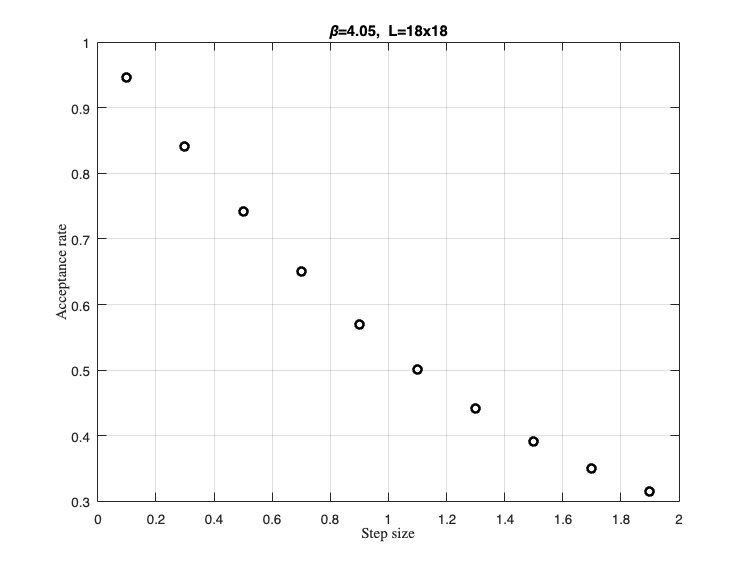

clear; clc; close all;
clear figure;

Beta=4.05;
L=18;

stepsize=[0.1,0.3,0.5,0.7,0.9,1.1,1.3,1.5,1.7,1.9];

accpt=zeros(size(stepsize));
tintQ=zeros(size(stepsize));
tintP=zeros(size(stepsize));
tintW4=zeros(size(stepsize));
tintW8=zeros(size(stepsize));

stdQ= zeros(size(stepsize));
stdP = zeros(size(stepsize));
stdW4=zeros(size(stepsize));
stdW8= zeros(size(stepsize));

for i =1:length(stepsize)

    filename=sprintf('Results_Stepsize%.1f_MHMA1_L%.fx%.f_B(%.2f).csv', stepsize(i),L,L,Beta);
    data= readtable(filename,'Delimiter',',','NumHeaderLines',1,'ReadVariableNames', false,'TextType', 'string');

    labels= data.Var1;
    values= str2double(string(data.Var2));
    third= str2double(string(data.Var3));

    accpt(i)= values(strcmp(labels,'Acceptance Rate'));
    tintQ(i) =values(strcmp(labels,'Q T_int (Py-uwerr)'));
    tintP(i)= values(strcmp(labels, 'Plaquette T_int (Py-uwerr)'));
    tintW4(i) = values(strcmp(labels,'W4x4 T_int (Py-uwerr)'));
    tintW8(i) = values(strcmp(labels,'W8x8 T_int (Py-uwerr)'));

    stdQ(i)= third(strcmp(labels, 'Q T_int (Py-uwerr)'));
    stdP(i)=third(strcmp(labels, 'Plaquette T_int (Py-uwerr)'));
    stdW4(i)= third(strcmp(labels, 'W4x4 T_int (Py-uwerr)'));
    stdW8(i)= third(strcmp(labels, 'W8x8 T_int (Py-uwerr)'));

end

%testf= fit(stepsize.', accpt.', 'gauss2')

figure(1)
plot(stepsize,accpt,'ko','LineWidth',2)
grid on
xlabel('Step size','Interpreter','latex')
ylabel('Acceptance rate', 'Interpreter','latex')
title(['\beta=', num2str(Beta),', L=', num2str(L),'x',num2str(L)])

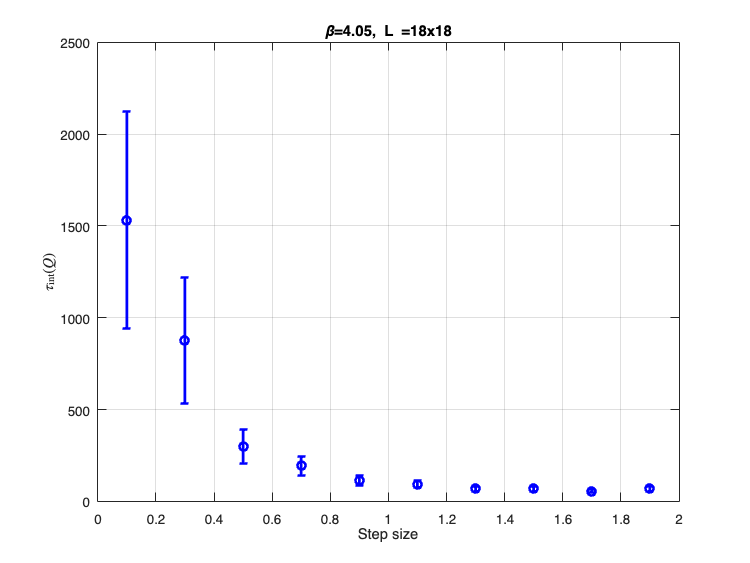


figure(2)
errorbar(stepsize,tintQ,stdQ,'bo','LineWidth',2)
grid on
xlabel('Step size')
ylabel('$\tau_{\mathrm{int}}(Q)$','Interpreter','latex')
title(['\beta=',num2str(Beta),', L =',num2str(L),'x',num2str(L)])

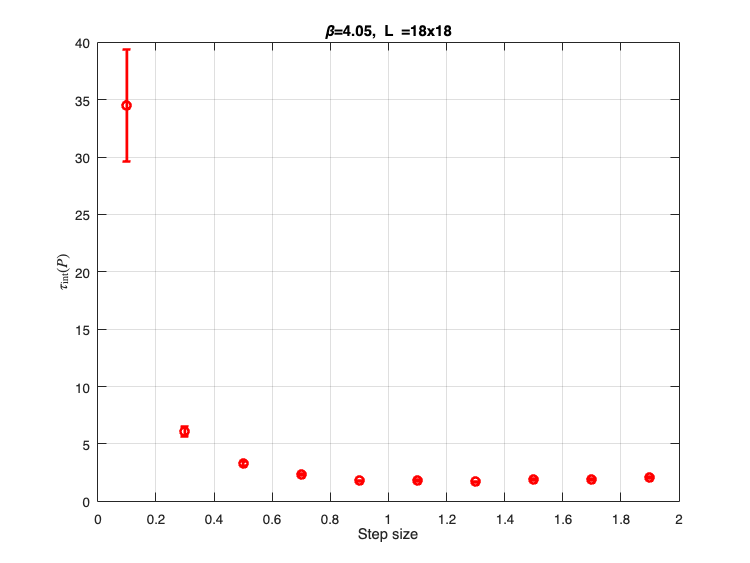


figure(3)
errorbar(stepsize,tintP,stdP,'ro','LineWidth',2)
grid on
xlabel('Step size')
ylabel('$\tau_{\mathrm{int}}(P)$', 'Interpreter', 'latex')
title(['\beta=', num2str(Beta), ', L =', num2str(L),'x',num2str(L)])

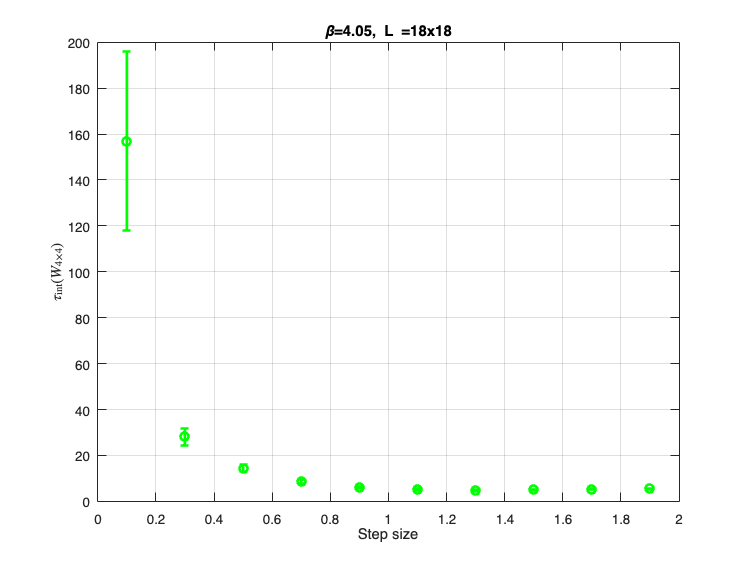


figure(4)
errorbar(stepsize, tintW4, stdW4, 'go', 'LineWidth', 2)
grid on
xlabel('Step size')
ylabel('$\tau_{\mathrm{int}}(W_{4\times4})$', 'Interpreter', 'latex')
title(['\beta=', num2str(Beta),', L =', num2str(L), 'x', num2str(L)])

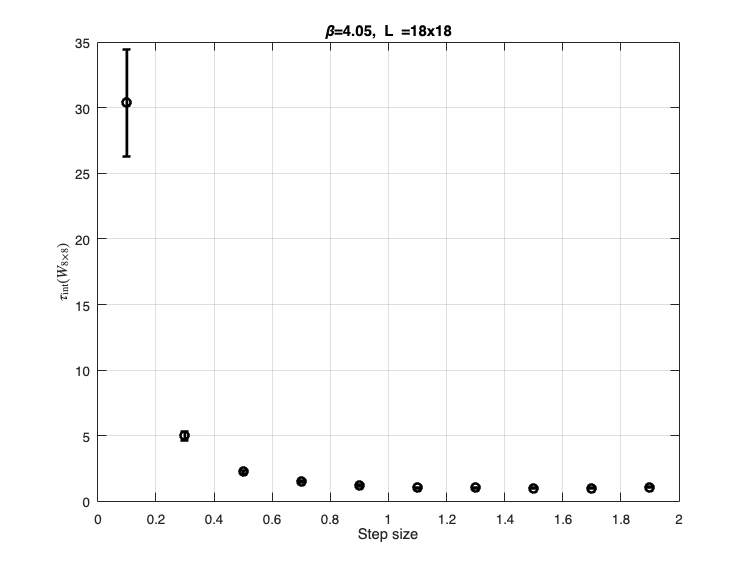


figure(5)
errorbar(stepsize,tintW8,stdW8,'ko','LineWidth',2)
grid on
xlabel('Step size')
ylabel('$\tau_{\mathrm{int}}(W_{8\times8})$', 'Interpreter', 'latex')
title(['\beta=', num2str(Beta),', L =', num2str(L),'x', num2str(L)])